# ouverture image

## flitre trouge

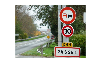


route70 = imread("s_p10.png");
route70 = im2double(route70);
figure(1)
imshow(route70)

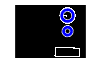


%conversion en hsv
route70hsv = rgb2hsv(route70);

hue = route70hsv(:,:,1);
sat = route70hsv(:,:,2);
val = route70hsv(:,:,3);

%imshow(hue)
%imshow(sat)
%imshow(val)

masque = zeros(size(hue));
masque (hue<0.06 & hue>=0 & sat > 0.3) = 1;
masque (hue>0.90 & hue<=1 & sat > 0.3) = 1;

SE = strel("disk",2);

masque = imerode(masque,SE);
masque = imdilate(masque,SE);

imshow(masque)
masque = 1-masque;

Rmin = 10;
Rmax = 300;

[centersBright, radiiBright] = imfindcircles(masque,[Rmin Rmax],'Sensitivity',0.92);
viscircles(centersBright, radiiBright,'Color','b');

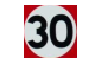


Roundcenter = round(centersBright);
Roundradius = round(radiiBright);

S = cell(length(Roundradius),1);

for i=1:length(Roundradius)
    A =  zeros(Roundradius(i)*2);
    for j=1:3
        S{i}(:,:,j) = A;
    end
end
for i=1:length(Roundradius)
    S{i} = route70(Roundcenter(i,2)-Roundradius(i):Roundcenter(i,2)+Roundradius(i) ...
                   ,Roundcenter(i,1)-Roundradius(i):Roundcenter(i,1)+Roundradius(i), ...
                   :);
end

imshow(S{1})

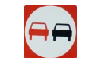

imshow(S{2})